## Quantitative Methods 3

### Problem Set 2

**Problem 1: Forecasting theory**

ARMA(1,2) process:


$$y_t = c+ \phi_1y_{t-1} + \theta_1\epsilon_{t-1} + \theta_2\epsilon_{t-2} + \epsilon_t , \epsilon_t \sim iid N(0, \sigma^2)$$


- Optimal MSE-point forecast for h=1 and h=2.


$$y_{T+1} = c + \phi_1y_T + \theta_1\epsilon_T + \theta_2\epsilon_{T-1} + \epsilon_{T+1}$$



$$\hat{y_{T+1}} = E_T(\mu + \phi_1(y_T - \mu) + \theta_1 \epsilon_T + \theta_2\epsilon_{T-1} + \epsilon_{T+1})$$



$$\hat{y_{T+1}} = \mu + \phi_1(y_T - \mu ) + \theta_1\epsilon_T + \theta_2\epsilon_{T-1} $$



$$\hat{y_{T+2}}= E_T ( \mu + \phi_1(\mu + \phi_1 (y_T - \mu)+\theta_1\epsilon_T+ \theta_2\epsilon_{T-1} + \epsilon_{T+1})-\mu) + \theta_1\epsilon_{T+1} + \theta_2\epsilon_T+ \epsilon_{T+2}) \\
\hat{y_{T+2}}= \mu + \phi_1^2(y_T - \mu) + \phi_1\theta_1\epsilon_T + \phi_1\theta_2\epsilon_{T-1} + \theta_2\epsilon_T$$


**Problem 3: Forecasting practice**

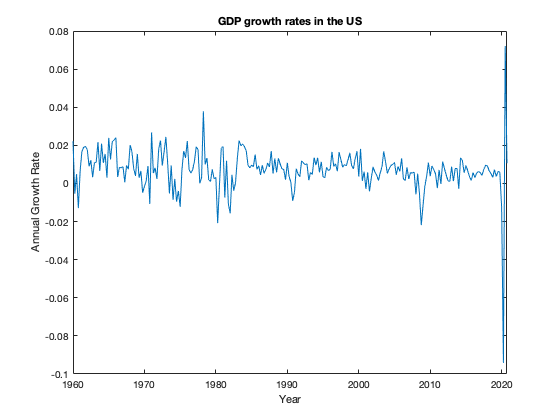

cd('/Users/nesgueven/Master ITFD/Term 3/Quantitative Methods III/');
GDPC1 = readtable("GDPC1.xls");
T = datetime(1947,01,01,"Format","dd-MMM-uuuu"):calmonths(3):datetime(2021,01,01,"Format","dd-MMM-uuuu");
T = T(2:end)';
gdp = GDPC1(:,"GDPC1");
gdp = double(table2array(gdp));
returns = price2ret(gdp, [], 'Continuous');
% plot
figure;
plot(T(52:295), returns(52:295));
title("GDP growth rates in the US");
xlabel('Year');
ylabel('Annual Growth Rate');

2. Estimate M1 and M2